# Parameter Fitting and Design Optimization

Maurizio Clemente and Finn Vehlhaber

In this exercise we first fit a convex model to a given motor map using semi-definite programming. Then, we leverage the obtained formulation in a vehicle model in order to solve a design optimizaiton problem. This live script makes reference to **Exercise 5** in the handout.

**Run the sections one by one by clicking into the respective code window and hitting "Run Section". Sentences highlighted in bold give instructions on how to complete the given code. Code lines like this need to be completed by you:**

% ----- complete code here
% (incomplete code here)
% -----

## Parameter Fitting

As a first step we want to obtain an analytical motor model from a given efficiency lookup table. Due to the shape of the given motor map, we choose to represent it with part of an ellipsoid, as this closely resembles the exisiting map.

clear; close all; clc;

% load motor data
load Ex5Data.mat

**Fit an ellipsoid **$P_\mathrm{loss} = \mathbf{x}^\top Q \mathbf{x}$** with **$\mathbf{x} = [1 \, , \, \omega \, , \, P_\mathrm{m}\, ]$** to the motor map to obtain a convex loss model.**

*Hint: The command *`sum((Q*X).*X)`* with *$\texttt{X=}\; \left[ {\mathbb{1}^\top \atop [\omega_1,\omega_2,\dots,\omega_N ] \atop [P_{\mathrm{m},1},P_{\mathrm{m},2},\dots,P_{\mathrm{m},N}]} \right]$* results in the row vector *$[ \mathbf{x}_1^\top Q \mathbf{x}_1 \;\; \mathbf{x}_2^\top Q \mathbf{x}_2 \dots \mathbf{x}_N^\top Q \mathbf{x}_N]$, where $\mathbf{x}_i^\top Q \mathbf{x}_i$ corresponds to data point $P_{\mathrm{loss},i}$ in the motor map.

% only consider the positive torque section
T_m     = motor.shaftTorque(:,1:29);
P_m     = motor.shaftPower(:,1:29);
omega   = motor.speed(:,1:29)*pi/30;
eta     = motor.efficiency(:,1:29);

% obtain the motor map for the positive torque section
P_loss   = motor.totalLoss(:,1:29);

% Normalization constants
EbN    = 1e8;
PmN     = 1e5;
omegaN  = 1e3;

% ----- complete code here
% concatenate x vectors into X
X = [ones(size(P_m(:)))';
        omega(:)'/omegaN;
        P_m(:)'/PmN];

% optimization variable
Q = sdpvar(3);
% -----
P_loss_model = sum((Q*X).*X);

constraints = [ 
    % ----- complete code here
    Q               >= 0;
    % -----
    P_loss_model    >= 0];

% find best fit with least-error squared
objective   = norm(P_loss_model - (P_loss(:)')./PmN);
options     = sdpsettings('solver', 'mosek','verbose',2);
optimize(constraints, objective, options);

MOSEK Version 10.1.21 (Build date: 2023-12-1 10:48:53)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: MACOSX/aarch64

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 7               
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 1               
  Scalar variables       : 2263            
  Matrix variables       : 1 (scalarized: 6)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 2                 time                   : 0.00            
Lin. dep.  - tries                  :


Q = value(Q);

Plot the fitted model on the motor map to check the accuracy.

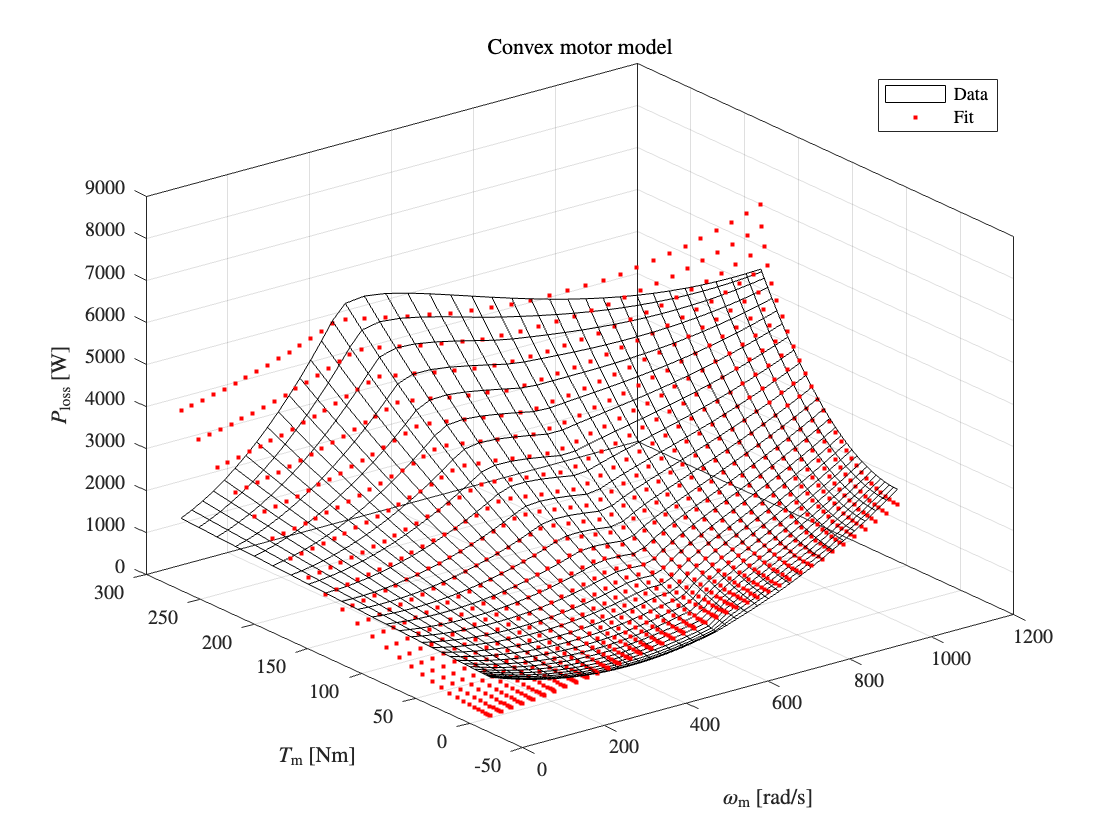

P_loss_model    = reshape(sum((Q*X).*X).*PmN,size(P_m));

figure;
hold on
surf(omega, T_m, P_loss_model,'FaceColor','none')
plot3(omega,T_m,P_loss,'r.')
view(3)
grid on; box on;
xlabel('$\omega_\mathrm{m}$ [rad/s]','Interpreter','latex')
ylabel('$T_\mathrm{m}$ [Nm]','Interpreter','latex')
zlabel('$P_\mathrm{loss}$ [W]','Interpreter','latex')
set(gca,'ticklabelinterpreter','latex')
title('Convex motor model','Interpreter','latex')
legend('Data','Fit','Interpreter','latex','Location','northeast')

## Design Optimization Problem

Now we want to design a fixed transmission between motor and wheels to reduce the energy consumption of our electric vehicle. Use the structs `vehicle` and `wltp `for the vehicle parameters and drive cycle.

% calculate requested power
% ----- complete code here
P_req = vehicle.mass * diff([0;wltp3.velocity]).*wltp3.velocity + ...
        .5 * vehicle.rho * vehicle.dragCoefficient * vehicle.frontalArea * wltp3.velocity.^3;
% -----
P_m   = P_req.*(P_req >= 0) * 1/vehicle.gearboxEfficiency + ...
        P_req.*(P_req < 0) * vehicle.gearboxEfficiency;

Plot your results

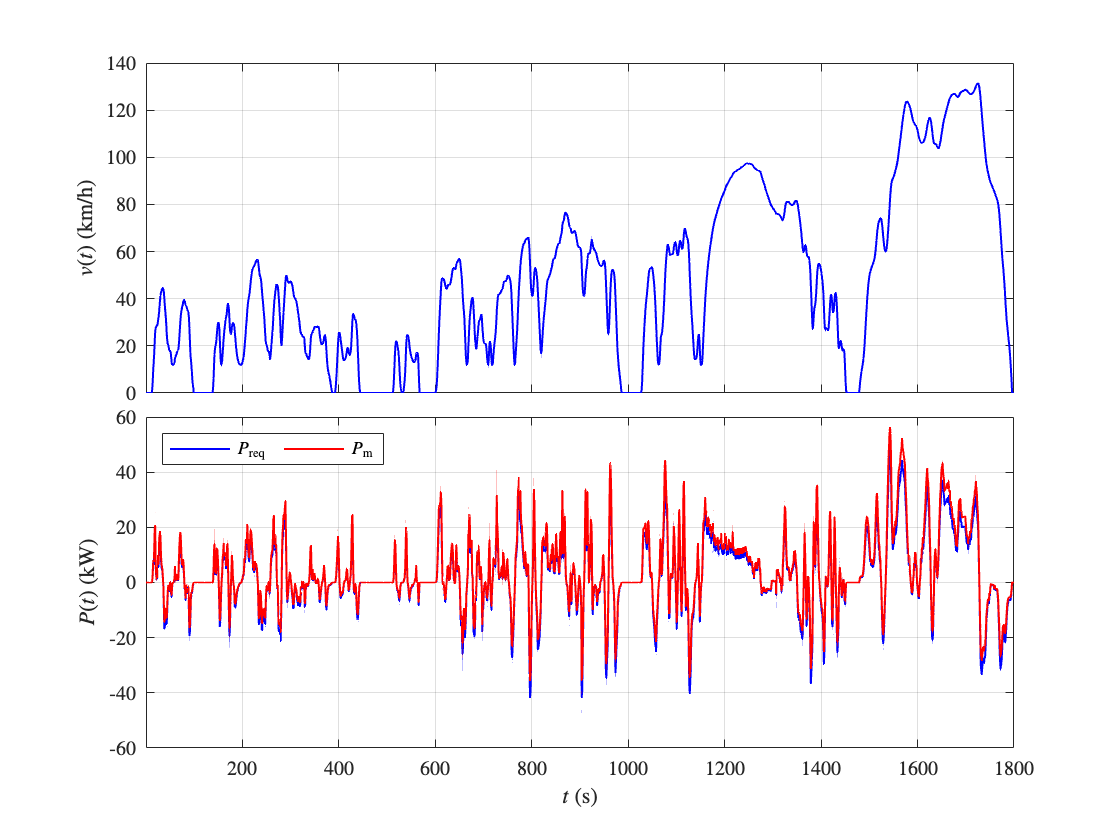

% plots
figure;
tiledlayout(2,1, "TileSpacing","tight");
% drive cycle velocity profile
nexttile
plot(wltp3.time,wltp3.velocity*3.6,'b','linewidth',1);
grid on; box on;
set(gca,'ticklabelinterpreter','latex','xticklabels',[]);
ylabel('$ v(t)$ (km/h)','Interpreter','latex');
xlim([1 wltp3.time(end)])

% requested power at the wheels 
nexttile
hold on
plot(wltp3.time,P_req/1e3,'b','linewidth',1,'DisplayName','$P_\mathrm{req}$');
plot(wltp3.time,P_m/1e3,'r','linewidth',1,'DisplayName','$P_\mathrm{m}$');
grid on; box on;
set(gca,'ticklabelinterpreter','latex');
ylabel('$ P(t)$ (kW)','Interpreter','latex');
xlabel('$ t$ (s)','Interpreter','latex');
xlim([1 wltp3.time(end)])
legend('Location','northwest','Interpreter','latex','orientation','horizontal');

Develop the power train model and optimize the gear ratio.

N = length(wltp3.time);
% ----- complete code here
% obtain angular velocity of the wheels throughout the drive cycle
omega_w =  wltp3.velocity'/vehicle.wheelRadius;
% -----

% -- optimization variables --
% state
dE_b = sdpvar(1,N);
% input
gamma = sdpvar(1);
% lifting
P_b = sdpvar(1,N);
P_loss = sdpvar(1,N);
omega_m = sdpvar(1,N);

% assemble x vector, use the same normalization constants as in the fitting
% exercise
% ----- complete code here
x = [ones(1,N);...
    omega_m;...
    abs(P_m')/PmN];
% -----

% constraints
constraints = [
    % ----- complete code here
    P_b     == (P_m'/PmN + P_loss)
    dE_b    == P_b * triu(ones(N)) * PmN /EbN
    P_loss  >= sum((Q*x).*x)
    omega_m == gamma * omega_w/omegaN

    omega_m <= 1e4/omegaN
    gamma   >= 5;
    gamma   <= 10;
    % -----
];
% ----- complete code here
objective = dE_b(end);
% -----
options     = sdpsettings('solver', 'mosek','verbose',2);
optimize(constraints, objective, options);

MOSEK Version 10.1.21 (Build date: 2023-12-1 10:48:53)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: MACOSX/aarch64

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 7201            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 1800            
  Scalar variables       : 12602           
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 4933
Eliminator terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 2                 time                   : 0.00            
Lin. dep.  - tries                 

Plot results

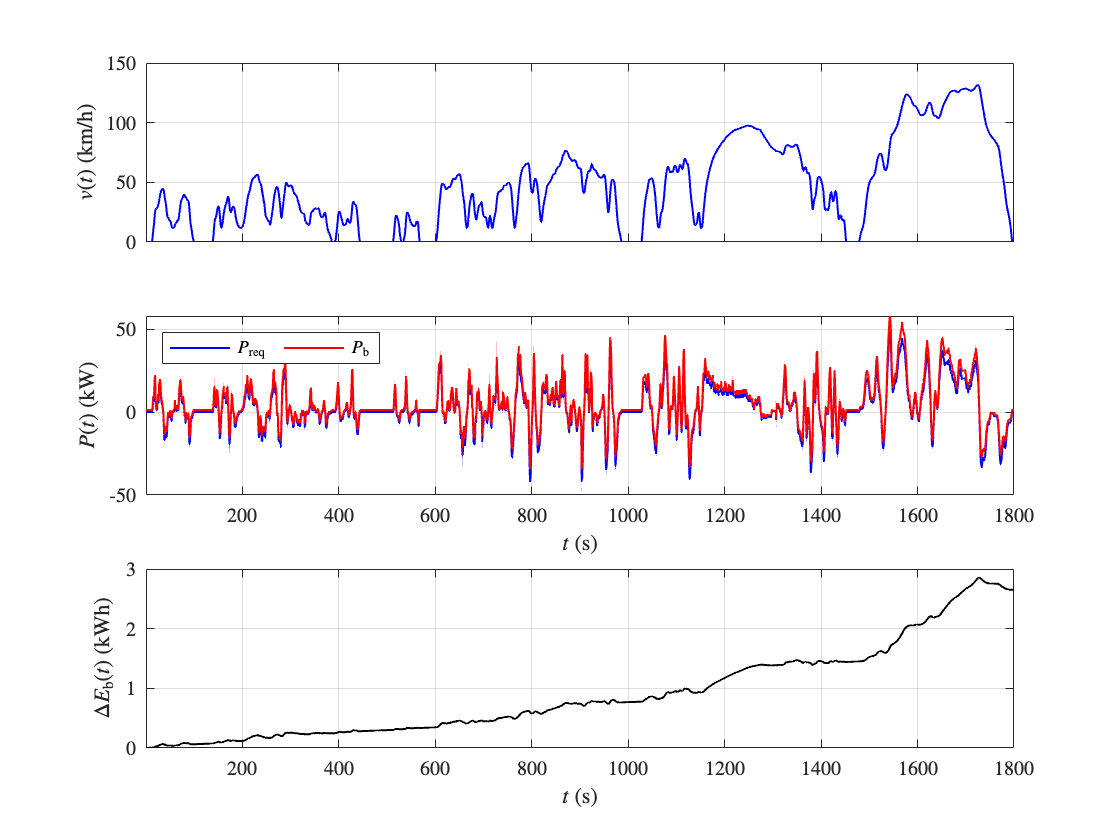

% plots
figure;
tiledlayout(3,1, "TileSpacing","tight");
% drive cycle velocity profile
nexttile
plot(wltp3.time,wltp3.velocity*3.6,'b','linewidth',1);
grid on; box on;
set(gca,'ticklabelinterpreter','latex','xticklabels',[]);
ylabel('$ v(t)$ (km/h)','Interpreter','latex');
xlim([1 wltp3.time(end)])

% requested power at the wheels 
nexttile
hold on
plot(wltp3.time,P_req/1e3,'b','linewidth',1,'DisplayName','$P_\mathrm{req}$');
plot(wltp3.time,value(P_b)*PmN/1e3,'r','linewidth',1,'DisplayName','$P_\mathrm{b}$');
grid on; box on;
set(gca,'ticklabelinterpreter','latex');
ylabel('$ P(t)$ (kW)','Interpreter','latex');
xlabel('$ t$ (s)','Interpreter','latex');
xlim([1 wltp3.time(end)])
legend('Location','northwest','Interpreter','latex','orientation','horizontal');

% evolution of battery energy
nexttile
hold on
plot(wltp3.time,value(dE_b)*EbN/3600/1e3,'k','linewidth',1,'DisplayName','$P_\mathrm{b}$');
grid on; box on;
set(gca,'ticklabelinterpreter','latex');
ylabel('$ \Delta E_\mathrm{b}(t)$ (kWh)','Interpreter','latex');
xlabel('$ t$ (s)','Interpreter','latex');
xlim([1 wltp3.time(end)])

Plot Operating Points

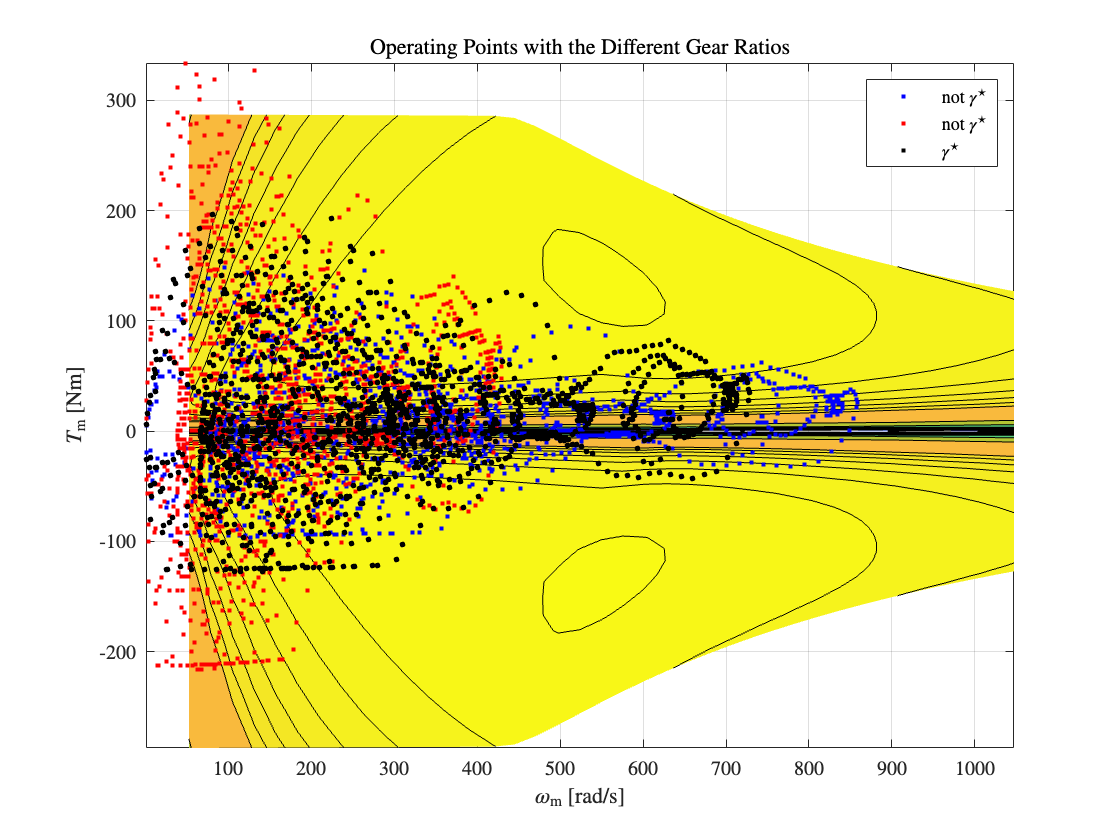

% plot operating points
figure;
hold on
contourf(omega, T_m, eta,[0:10:90,91:99],'HandleVisibility','off');
contourf(omega, -T_m, eta,[0:10:90,91:99],'HandleVisibility','off');
scatter(omega_w*8,P_m./wltp3.velocity/9*vehicle.wheelRadius,36,'b','.','DisplayName','not $\gamma^\star$')
scatter(omega_w*4,P_m./wltp3.velocity/4*vehicle.wheelRadius,36,'r','.','DisplayName','not $\gamma^\star$')
scatter(value(omega_m)*omegaN,P_m./wltp3.velocity/value(gamma)*vehicle.wheelRadius,72,'k','.','DisplayName','$\gamma^\star$')
grid on; box on;
xlabel('$\omega_\mathrm{m}$ [rad/s]','Interpreter','latex')
ylabel('$T_\mathrm{m}$ [Nm]','Interpreter','latex')
set(gca,'ticklabelinterpreter','latex')
title('Operating Points with the Different Gear Ratios','Interpreter','latex')
legend('Location','northeast','Interpreter','latex')